# Ex1_TwoOscillators

We apply our control design framework to an 2-dof Oscillator Chain with cubic and quadratic nonlinearities as follows.

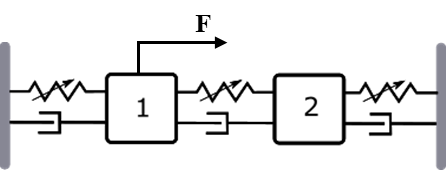

Here we place a control force at the first oscillator. 

clear all; close all; clc

## Example setup

n = 2;    % number of oscillators
mass = 1;  % mass
k = 1;     % stiffness
c = 0.1;   % damping
kappa2 = 0;   % quadratic nonlinearity
kappa3 = 0.75; % cubic nonlinearity
[K,C,f2,f3] = assemble_global_coefficients(k,kappa2,kappa3,c,n);

**Dirichlet boundary conditions**

K = K(2:n+1,2:n+1);
C = C(2:n+1,2:n+1);
M = mass*speye(n,n);
f3 = f3(2:n+1,2:n+1,2:n+1,2:n+1);

#### Dynamical System Setup

The dynamic equation of the 2-dof Oscillator Chain is as follows


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon(\mathbf{u}(t)+\mathbf{f}^{ext}({\Omega}t)),$$


where the detailed form is 

$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\ddot{x} }_1 \\
{\ddot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0\ldotp 2 & -0\ldotp 1\\
-0\ldotp 1 & 0\ldotp 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
x_1^3 -{\left(x_2 -x_1 \right)}^3 \\
{\left(x_2 -x_1 \right)}^3 -x_2^3 
\end{array}\right\rbrack =\epsilon \left(\left\lbrack \begin{array}{c}
u\\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\sin \left(0\ldotp 1\sqrt{2}t\right)\\
0
\end{array}\right\rbrack \right)$,

which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}({\phi}),\dot{\phi}	
=\Omega.$$


The detailed form

$\left\lbrack \begin{array}{cccc}
0\ldotp 2 & -0\ldotp 1 & 1 & 0\\
-0\ldotp 1 & 0\ldotp 2 & 0 & 1\\
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 \\
{\ddot{x} }_1 \\
{\ddot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-2 & 1 & 0 & 0\\
1 & -2 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
x_1^3 -{\left(x_2 -x_1 \right)}^3 \\
{\left(x_2 -x_1 \right)}^3 -x_2^3 \\
0\\
0
\end{array}\right\rbrack +\epsilon \left(\left\lbrack \begin{array}{c}
u\\
0\\
0\\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\sin \left(0\ldotp 1\sqrt{2}t\right)\\
0\\
0\\
0
\end{array}\right\rbrack \right)$.

where 


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',{[],f3});
set(DS.Options,'Emax',4,'Nmax',10,'notation','multiindex')
outdof = [1 2];
set(DS.Options, 'outDOF', outdof);

**Add external forcing and also control matrix to dynamical system**

Bext     = zeros(n,1); Bext(1,1)=1;
ExtForce = @(t) Bext*sin(0.1*sqrt(2)*t);
epsilon  = 1e-3;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

#### Linear Modal analysis

We solve generalized eigenvalue problem


$$\mathbf{A}\mathbf{V}=\mathbf{B}\mathbf{V}\mathbf{D}$$


where $\mathbf{V}=(\mathbf{v}_1,\cdots,\mathbf{v}_n)$ and $\mathbf{D}=\mathrm{diag}\{\lambda_1,\cdots,\lambda_n\}$ such that $\mathbf{A}\mathbf{v}_i=\lambda_i\mathbf{B}\mathbf{v}_i$. We also calculate the left eigenvectors $\mathbf{U}=(\mathbf{u}_1,\cdots,\mathbf{u}_n)$ such that

$\mathbf{U}^\ast\mathbf{A}=\mathbf{D}\mathbf{U}^\ast\mathbf{B}$.

The eigenvectors are normalized in the folowing way

$\mathbf{U}^\ast\mathbf{B}\mathbf{V}=\mathbb{I}$.

[V,D,U] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i
  -0.1500 + 1.7255i
  -0.1500 - 1.7255i


#### SSM reduced dynamics - autonomous part

Firstly, we decompose the state vector $\mathit{\mathbf{z}}$ into a nonlinear part and a linear part via SSM based model order reduction, as follows

$\mathbf{z}(t)=\mathbf{W}(\mathbf{p}(t))+\epsilon\mathbf{X}_0(t)$.

And the reduced dynamics on the SSM can be expressed as

$\dot\mathbf{p}=\mathbf{R}(\mathbf{p})$.

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 3;
% master subspace
modes = [1 2];
S.choose_E(modes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2
These are in resonance with the follwing eigenvalues of the master subspace
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i
sigma_in = 3


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.92E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.06E-03 MB


auData = construct_autoData(DS, modes, R_0);

#### Linear model order reduction analysis

The above decomposition enables us to transform the original nonlinear optimal control into a linear optimal control problem of the same dimensionality. And the linear dynamics equation is shown below

$\mathbf{B}\mathbf{\dot{X}}_0(t)=\mathbf{A}\mathbf{X}_0(t)+\mathbf{F}^{ext}(t)+\mathbf{B}^{ext}\mathbf{u}(t)$.

The high-dimensional linear optimal control problem makes real-time control infeasible when n ≫ 1. To resolve the curse of high-dimensionality, we further perform a linear reduction to the high-dimensional linear system. We project the full state space of $\mathbf{X}_0$ to some $l$-dimensional spectral subspace. In particular, we have


$$\mathbf{X}_0=\hat\mathbf{V}\mathbf{q}(t),\quad \hat\mathbf{V}=(\hat\mathbf{v}_1,\cdots,\hat\mathbf{v}_n),\quad l\ll{n}.$$


With the above approximation, the decomposition of the original full nonlinear states are transformed to 

$\mathbf{z}(t)=\mathbf{W}(\mathbf{p}(t))+\epsilon\hat\mathbf{V}\mathbf{q}(t)$,

and the linear dynamics are updated as 

$\mathbf{B}\hat\mathbf{V}\mathbf{\dot{q}}(t)=\mathbf{A}\hat\mathbf{V}\mathbf{q}(t)+\mathbf{F}^{ext}(t)+\mathbf{B}^{ext}\mathbf{u}(t)$.

Then we pre-multiply both sides of the equation with $\mathbf{U}=(\mathbf{u}_1,\cdots,\mathbf{u}_l)$, and we have the reduced linear dynamics 

$\mathbf{\dot{q}}(t)=\mathbf{\hat\mathbf{\Lambda}}\mathbf{q}(t)+\hat{\mathbf{U}}^T\mathbf{F}^{ext}(t)+\hat{\mathbf{U}}^T\mathbf{B}^{ext}\mathbf{u}(t)$.

Here, we present two selection schemes: 

- based on direct current gains (DCgains)

- based on modal Hankel singular values (MHSVs)

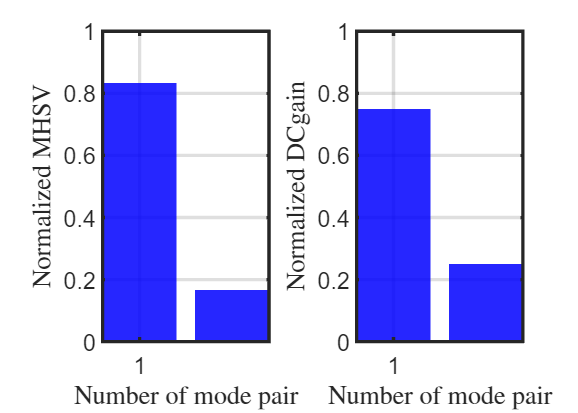

MHSV sum of the first 2 pairs
     1
DCgain sum of the first 2 pairs
     1


res = Linear_MOR(DS,n);

## Vibration with external force but without control 

For convenience, we set the initial value of reduced coordinates $\mathbf{p}_0=[0.5, 0.5]^\text{T}$, take $\mathbf{z}_0=\mathbf{W}(\mathbf{p}_0)$ as the initial conditions of the full system. In particular, the corresponding initial displacement of the first oscillator is 0.4583. At this large amplitude initial deformation the vibration decays very slowly by damping alone, see the result of *vibration with external force but without control*. 

% Construction of initial condition
p0 = [0.5 0.5]';
z0 = reduced_to_full(p0,W_0,[],0)+0.;
tf     = 20;
nsteps = 1000;

om = 2*pi/tf;
[tfullwoNL, xfullwoNL] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

**plot**

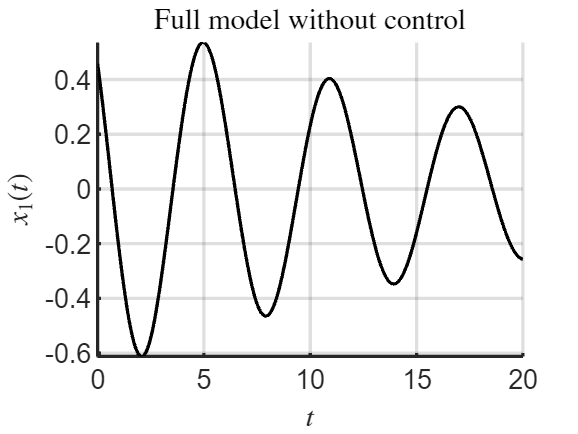

figure; hold on
plot(tfullwoNL, xfullwoNL(:,1),'k-','LineWidth',2);
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('Full model without control','Interpreter',"latex")
set(gca,'FontSize',16);
grid on
set(gca, 'LineWidth', 2);

## Closed loop control without receding horizon

So we need to apply suitable control to quickly suppress the vibration. In this code section we simulate the closed loop control without receding feedback. From the result, we observe that the simulated response of the full system matches well with that of the ROM-based prediction for t ∈ [0, 5], but starts to deteriorate for t ≥ 5.

% control parameters
cont   = struct();
cont.Q    = blkdiag(5e3*eye(n),zeros(n));
cont.Rhat = 0.01*eye(1);
cont.Mhat = 0*eye(2*n);

t0 = 0;
t1 = tf;

tspan = linspace(t0,t1,nsteps);
traj = LQR_closed_loop(DS,z0,'linear',tspan,auData,W_0,modes,1:4,cont);

pl
   0.5046 + 0.0470i
   0.5046 - 0.0470i
p0
   0.5046 + 0.0470i
   0.5046 - 0.0470i
Time for backward simulation of Riccati ODE is 5.685990e-02
Time for backward simulation of compensated ODE is 2.464038e-01
历时 0.397327 秒。
Time for forward simulation of ODEs for modal coordinates is 4.339102e-01



om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj.time,traj.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

**plot**

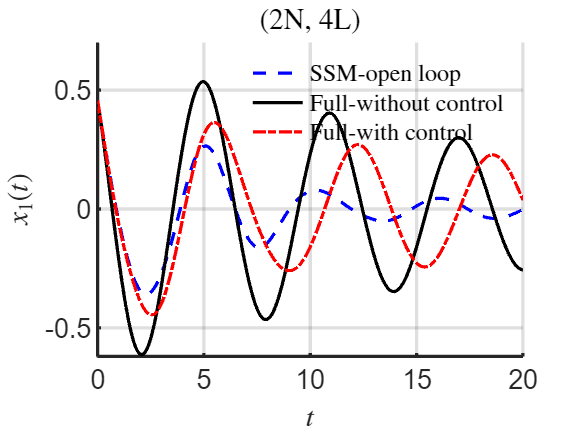

% displacement field
figure; hold on
plot(traj.time, traj.zt(1,:),'b--','DisplayName','SSM-open loop','LineWidth',2);
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfullwc1, xfullwc1(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on
% axis tight
set(gca, 'LineWidth', 2);
ylim([-0.62, 0.7])

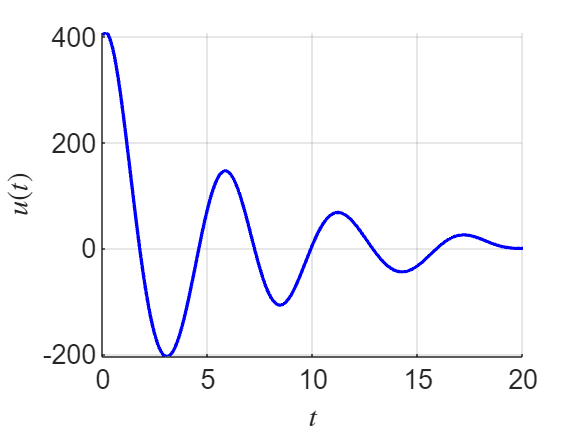


%  control input
figure; hold on;
plot(traj.time,traj.ut,'b-','DisplayName','SSM-open-control','LineWidth',2);
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight

## Closed loop control with 2 receding horizons

To address the deterioration, we apply the receding horizon control.  In particular, we divide the horizon [0, 20] into two subintervals with an intersection point at t = 5. We see that the response of the full system matches excellently with the ROM-based prediction at the second subinterval. This illustrates the effectiveness of the receding horizon control.

t0 = 0;
t1 = tf/4; % 5s
t2 = tf;   % 20s

**Time interval - 1**

om = 2*pi/t1;
tspan1 = linspace(t0,t1,nsteps);
traj_closed1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,modes,1:4,cont);

pl
   0.5046 + 0.0470i
   0.5046 - 0.0470i
p0
   0.5046 + 0.0470i
   0.5046 - 0.0470i
Time for backward simulation of Riccati ODE is 2.715020e-02
Time for backward simulation of compensated ODE is 5.782790e-02
历时 0.044435 秒。
Time for forward simulation of ODEs for modal coordinates is 1.419523e-01


ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1,xf,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

xf  = xf'; % initial condition for next interval

**Time interval - 2**

tspan2 = linspace(t1,t2,nsteps);
traj_closed2 = LQR_closed_loop(DS,xf,'linear',tspan2,auData,W_0,modes,1:4,cont);

pl
   0.1164 - 0.2072i
   0.1164 + 0.2072i
p0
   0.1164 - 0.2072i
   0.1164 + 0.2072i
Time for backward simulation of Riccati ODE is 1.960800e-02
Time for backward simulation of compensated ODE is 1.253477e-01
历时 0.265047 秒。
Time for forward simulation of ODEs for modal coordinates is 2.663005e-01


om = 2*pi/(t2-t1);
ufun = @(t) transpose(interp1(traj_closed2.time,traj_closed2.ut',t));
set(DS,'u',ufun);
[tfullwc2, xfullwc2,~,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',xf,'ts',t1);

**Plot - oscillator 1**

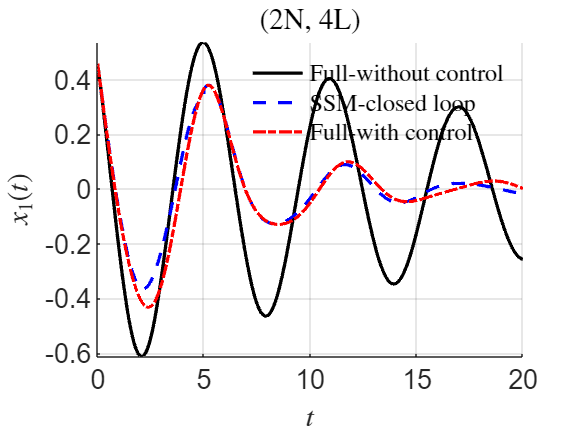

figure; hold on
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj_closed1.time, traj_closed2.time], [traj_closed1.zt(1,:),traj_closed2.zt(1,:)],...
                                             'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfullwc1; tfullwc2], [xfullwc1(:,1); xfullwc2(:,1)],...
                                             'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on, axis tight

**Plot - oscillator 2**

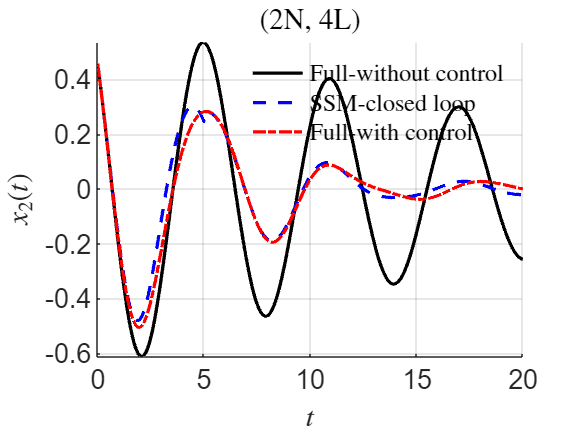

figure; hold on
plot(tfullwoNL, xfullwoNL(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj_closed1.time, traj_closed2.time], [traj_closed1.zt(2,:),traj_closed2.zt(2,:)],...
                                             'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfullwc1; tfullwc2], [xfullwc1(:,2); xfullwc2(:,2)],...
                                             'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(2)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on

**Plot - control inputs**

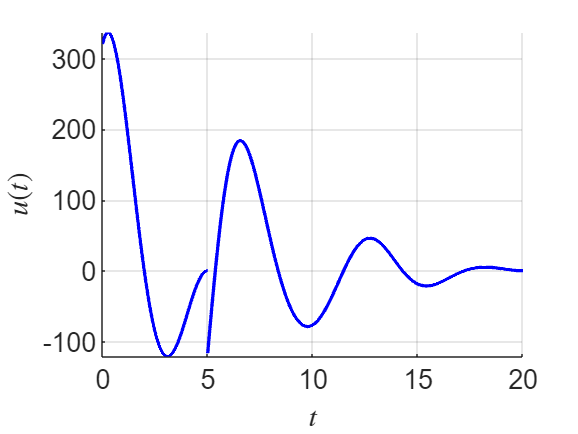

%  control input
figure; hold on;
plot(traj_closed1.time,traj_closed1.ut(1,:),'b-','LineWidth',2);
plot(traj_closed2.time,traj_closed2.ut(1,:),'b-','LineWidth',2);
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight